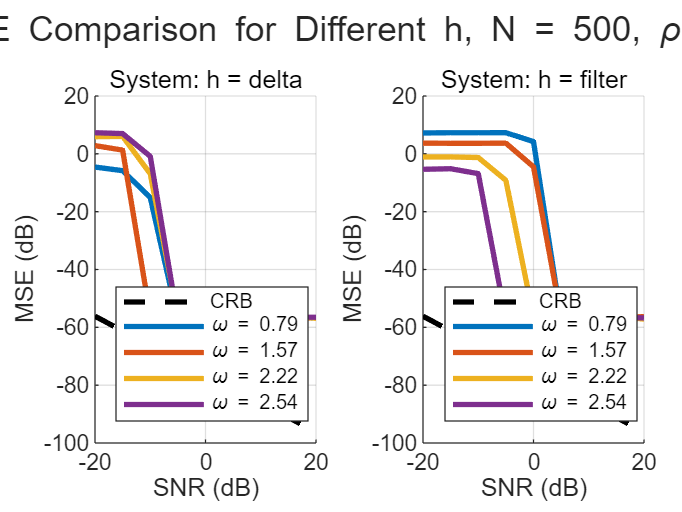

clc; clear;

%%%%% Parameters %%%%%
a0 = 1;
N = 500;
rho = 0.5;
omega_values = pi * [1/4, 1/2, 1/sqrt(2), 0.81];
SNR_dB = -20:5:20;
num_simulations = 20;

filter_coeffs.b = [2];
filter_coeffs.a = [1, 0.9];

color_map = lines(length(omega_values));
snr_linear = 10.^(SNR_dB / 10);
crb = compute_crb(N, snr_linear);  % one CRB for all

h_cases = ["delta", "filter"];  % system types

%%%%% Plot Setup %%%%%
figure;
tiledlayout(1, 2, 'Padding', 'compact', 'TileSpacing', 'compact');

for h_idx = 1:length(h_cases)
    h_case = h_cases(h_idx);
    nexttile;
    hold on;

    % Plot CRB once
    plot(SNR_dB, 10*log10(crb), 'k--', 'LineWidth', 2, 'DisplayName', 'CRB');

    for omega_idx = 1:length(omega_values)
        omega = omega_values(omega_idx);
        all_mse = zeros(num_simulations, length(SNR_dB));

        for sim = 1:num_simulations
            sim_result = simulate_estimation(N, SNR_dB, omega, rho, h_case, filter_coeffs, a0);
            all_mse(sim, :) = sim_result.MSE;
        end

        avg_mse = mean(all_mse, 1);
        plot(SNR_dB, 10*log10(avg_mse), '-', ...
            'Color', color_map(omega_idx, :), ...
            'LineWidth', 2, ...
            'DisplayName', sprintf('\\omega = %.2f', omega));
    end

    title(sprintf('System: h = %s', h_case));
    xlabel('SNR (dB)');
    ylabel('MSE (dB)');
    grid on;
    legend('Location', 'southwest');
    hold off;
end

sgtitle(sprintf('MSE Comparison for Different h, N = %d, \\rho = %.2f', N, rho));


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%% Supporting Functions %%%%%

function results = simulate_estimation(N, SNR_dB, omega, rho, h_case, filter_coeffs, a0)
results = struct();
results.MSE = zeros(1, length(SNR_dB));

for j = 1:length(SNR_dB)
    snr_lin = 10^(SNR_dB(j)/10);
    sigma_w2 = a0 / (2 * snr_lin);
    x = generate_signal(N, omega, sigma_w2, rho);

    if h_case == "filter"
        x = filter(filter_coeffs.b, filter_coeffs.a, x);
    end

    omega_est = estimate_frequency_fft(x, N);
    results.MSE(j) = (omega_est - omega)^2;
end
end

function x = generate_signal(N, omega, sigma_w2, rho)
phi_0 = 2 * pi * rand();
n = (0:N-1)';
s = cos(omega * n + phi_0);

% Generate correlated noise
Cww = sigma_w2 * rho.^abs((1:N)' - (1:N));
A = sqrt_covariance_matrix(Cww);
g = randn(N, 1);
w = A * g;

x = s + w;
end

function A = sqrt_covariance_matrix(Cww)
[Q, Lambda] = eig(Cww);
A = Q * sqrt(Lambda);
end

function omega_estimate = estimate_frequency_fft(x, N)
N_fft = 4 * N;
X = fft(x, N_fft);
mag = abs(X(1:floor(N_fft/2)));
[~, max_idx] = max(mag);
omega_fft = 2 * pi * (max_idx - 1) / N_fft;

% Fine search
K = 200;
search_range = linspace(omega_fft - pi/N_fft, omega_fft + pi/N_fft, K);
n = (0:N-1)';
cos_matrix = cos(n * search_range);
likelihoods = x' * cos_matrix;
[~, idx] = max(likelihoods);
omega_estimate = search_range(idx);
end

function crb = compute_crb(N, snr_linear)
crb = 6 ./ (snr_linear * N * (N - 1) * (2 * N - 1));
end
